# Statistical Estimation of Some High Dimensional Geometry

## Angle Distribution between 2 Random Vectors

Generally the higher the dimension, the more possible that 2 vectors are kind of orthogonal to each other, more precisely, the $\cos$ angle between 2 vectors will distribute center at 0, the std of which scale as $1/\sqrt D$, inverse to the scaling of norm expectation of a multi-variate unit Gaussian. For reference, 

In 10D space

`Angle in deg Mean 89.88, std 19.079`

`Cos Angle Mean 0.0020, std 0.3163`

In 50D space 

`Angle in deg Mean 90.07, std 8.147`

`Cos Angle Mean -0.0011, std 0.1408`

in 4096D space 

`Angle in deg Mean 90.00, std 0.883`

`Cos Angle Mean -0.0000, std 0.0154`

vec1 = zeros(1, dimen);
vec1(1) = 1; 
vec2 = randn(1, dimen);
vec2 = vec2 / norm(vec2); 

Pythagrian Estim 202.39

dot(vec1,vec2)

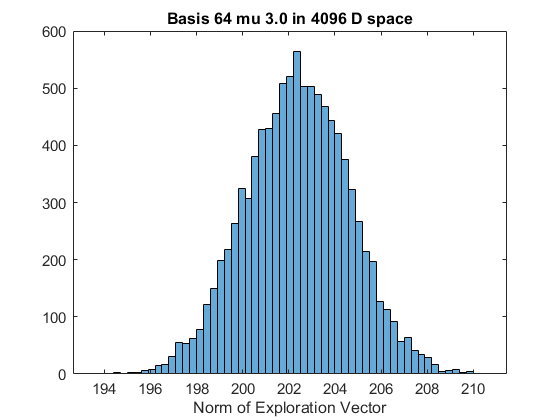

dimen = 10%4096; % 50
vec1 = zeros(1, dimen);
vec1(1) = 1; 
vec2 = randn(10000, dimen);
vec2 = vec2 ./ norm_axis(vec2,2); 
cosang = vec2 * vec1';

angs = acos(cosang);
angs_deg = angs / pi * 180;
figure, histogram(angs_deg), title(sprintf("Angle distribution of %d D random vector", dimen))
std(angs_deg) % spread of angle in degree ~ 0.9 deg
std(cosang) % spread of cosine angle between 2 vectors. % 0.015
fprintf("Angle in deg Mean %.2f, std %.3f\n" + ...
    "Cos Angle Mean %.4f, std %.4f", mean(angs_deg), std(angs_deg),...
    mean(cosang), std(cosang))

dimen = 4096%4096; % 50
vec1 = zeros(1, dimen);
vec1(1) = 1; 
vec2 = randn(10000, dimen);
vec2 = vec2 ./ norm_axis(vec2,2); 
cosang = vec2 * vec1';
angs = acos(cosang);
angs_deg = angs / pi * 180;
figure, histogram(angs_deg), title(sprintf("Angle distribution of %d D random vector", dimen))
std(angs_deg) % spread of angle in degree ~ 0.9 deg
std(cosang) % spread of cosine angle between 2 vectors. % 0.015
fprintf("Angle in deg Mean %.2f, std %.3f\n" + ...

    9.5154



    "Cos Angle Mean %.4f, std %.4f", mean(angs_deg), std(angs_deg),...
    mean(cosang), std(cosang))

Note the `cos` angle directly affects the norm of the sum of vectors, as in many of the cases `cos` will be small in high D, this summation will follow the rule of Pythagoras in many cases! 

### 
$$\|v+u\|=\sqrt{\|u\|^2+\|v\|^2+2\|u\|\|v\|cos(u,v)}$$


## Norm of Exploration Vector 

Compute the norm of exploration vector $u$ given a basis vector $v$ of certain norm and a $\mu$ of exploration. 


$$u=v+\mu T\\
T\sim \mathcal N(0,I)$$


In the essence this is just using the `cos` angle distribution above, 


$$\|v+u\|=\sqrt{\|u\|^2+\|v\|^2+2\|u\|\|v\|cos(u,v)}$$


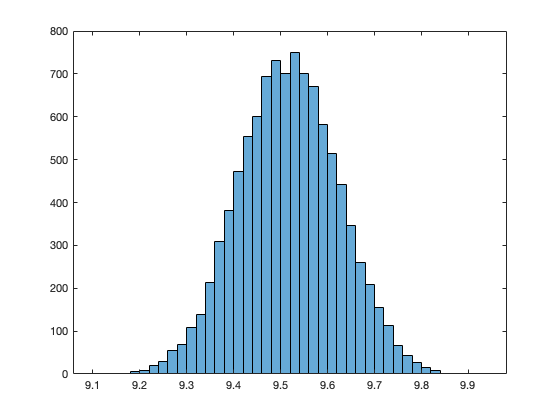

basis_norm = 64;

mu = 3;

Mean norm of grad 9.517, std 0.105

dimen = 4096; 
fprintf("Pythagrian Estim %.2f", sqrt(basis_norm.^2+mu^2*dimen))

ans = 9.5174

ans = 0.1054

basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 

Pure Noise Score	Mean norm of grad 9.517, std 0.105

tang_codes = mu * randn(10000, dimen);
new_codes = basis_vec+tang_codes;
newnorms = sqrt(sum(new_codes.^2,2));
figure, clf, histogram(newnorms), xlabel("Norm of Exploration Vector")
title(sprintf("Basis %.f mu %.1f in %d D space", basis_norm, mu, dimen))

## Step Size Expectation

Script to compute the statistical expectation of the step size, given 

dimen = 4096; 

    9.5154



pop_size = 40;
weights = rankweight(pop_size,pop_size/2);
mu = 0.5;
basis_norm = 100;

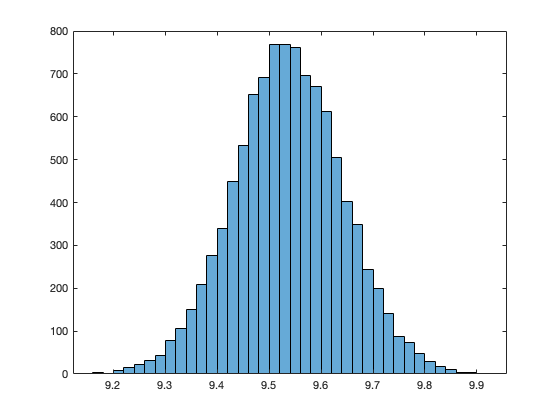

grad_vect = randn(1, dimen);

score_lin = @(x) x * grad_vect';

Linear Model Score	Mean norm of grad 9.537, std 0.105

## Compute the expected gradient norm

Given a reference vector and a Gaussian sample around it, score them by different models, and use CMAES type weighted average mechanism to compute gradient. 

%% Pure noise score
score_fun = @(x) randn(size(x,1),1);

dimen = 10

basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)
gradnorm_ctr=zeros(1,10000);
for i = 1:10000
tang_codes = mu * randn(pop_size, dimen);
f_basis = score_fun(basis_vec);

    0.4702



f_exp = score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);
gradnorm_ctr(i) = norm(hagrad);
end
figure, clf, histogram(gradnorm_ctr)
fprintf("Pure Noise Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm_ctr), std(gradnorm_ctr))

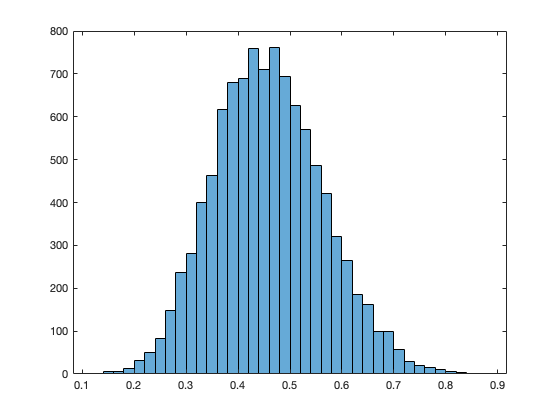

mean(gradnorm_ctr)

std(gradnorm_ctr)

Pure Noise, Mean norm of grad 0.459, std 0.105

fprintf("Pure Noise Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm_ctr), std(gradnorm_ctr))

score_fun = score_lin;

ans = 1.0448

basis_vec = zeros(1, dimen);

ans = 0.1026

basis_vec(1) = basis_norm; 

Pure Noise Score	Mean norm of grad 1.045, std 0.103

ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)

dimen = 10

gradnorm=zeros(1,10000);
for i = 1:10000
tang_codes = mu * randn(pop_size, dimen);
f_basis = score_fun(basis_vec);
f_exp = score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);

    0.4702



gradnorm(i) = norm(hagrad);
end
figure, clf, histogram(gradnorm)
fprintf("Linear Model Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm), std(gradnorm))
mean(gradnorm)
std(gradnorm)

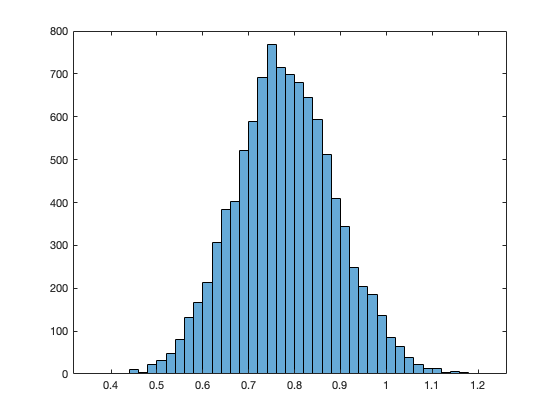

%% Low dimension case
dimen = 10

grad_vect = randn(1, dimen);

Linear Model, Mean norm of grad 0.780, std 0.110

score_lin = @(x) x * grad_vect';

ans = 0.7798

%% Pure noise score

ans = 0.1101

score_fun = @(x) randn(size(x,1),1);
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)
gradnorm_ctr=zeros(1,10000);
for i = 1:10000
tang_codes = mu * randn(pop_size, dimen);
f_basis = score_fun(basis_vec);
f_exp = score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);
gradnorm_ctr(i) = norm(hagrad);
end
figure, clf, histogram(gradnorm_ctr)
fprintf("Pure Noise, Mean norm of grad %.3f, std %.3f", mean(gradnorm_ctr), std(gradnorm_ctr))

mean(gradnorm_ctr)
std(gradnorm_ctr)
fprintf("Pure Noise Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm_ctr), std(gradnorm_ctr))

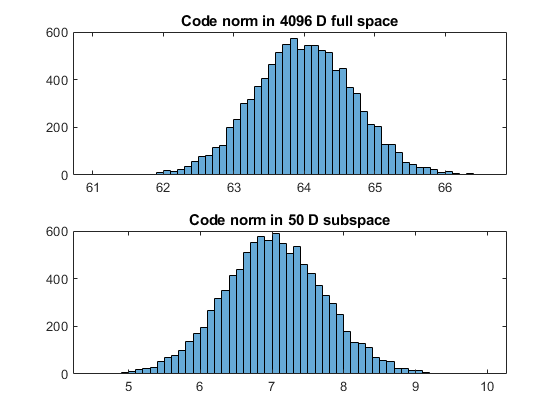

dimen = 10
grad_vect = randn(1, dimen);
score_lin = @(x) x * grad_vect';
score_fun = score_lin;
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)
gradnorm=zeros(1,10000);
for i = 1:10000

tang_codes = mu * randn(pop_size, dimen);

Expected norm in full space 64.00 std 0.0156

f_basis = score_fun(basis_vec);
f_exp = score_fun(basis_vec + tang_codes);

ans = 0.7067

[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);
gradnorm(i) = norm(hagrad);
end
figure, clf, histogram(gradnorm)
fprintf("Linear Model, Mean norm of grad %.3f, std %.3f", mean(gradnorm), std(gradnorm))
mean(gradnorm)
std(gradnorm)

**Conclusion: **Generally, with a single linear model (only 1d affects the score linearly, invariant to all other d.) the expected gradient norm should be higher than the expected gradient norm in the pure noise case. However, **the higher the dimension the smaller the effect**, and in 4096 D, effectively, we cannot tell if there is gradient or not from 40 samples just by looking at gradient norm! 

**Implication: **The CMA-ES tries to scale the exploration by looking at the "gradient" step and compare it to the expected value. 

### Results

In 4096 Dimension, either using a linear model or a random noise model as score the rank based weighted sum of the samples will be same of similar norm. (estimated from 10000 run simulation. )

`Pure Noise, Mean norm of grad 9.517, std 0.105`

`Linear Model, Mean norm of grad 9.537, std 0.105`

In 50 D, Same experiment (40 sample population)

`Pure Noise, Mean norm of grad 1.045, std 0.103`

`Linear Model, Mean norm of grad 1.222, std 0.107`

In 10 D, Same experiment 

`Pure Noise, Mean norm of grad 0.459, std 0.105`

`Linear Model, Mean norm of grad 0.780, std 0.110`

## Norm of Random Projection

Choose a 50d random subspace, and project a bunch of random vectors in high dimensional space to this subspace. See the change of norm. 

dimen = 4096;
subspace_d = 50;
basis = randbasis(dimen, subspace_d);
codes = randn(10000,dimen);
proj_code = codes * (basis' * basis);

figure;clf;hold on
subplot(211)
histogram(norm_axis(codes, 2))
title(compose("Code norm in %d D full space", dimen))
subplot(212)
histogram(norm_axis(proj_code, 2))
title(compose("Code norm in %d D subspace", subspace_d))
fprintf("Expected norm in full space %.2f std %.4f", sqrt(dimen), 1/sqrt(dimen))

std(norm_axis(proj_code, 2))

function basis = randbasis(dimen, basis_n)
subspacedim = basis_n; %varargin(1); %  
code_length = dimen;
basis = zeros(subspacedim, code_length);
for i = 1:subspacedim
    tmp_code = randn(1, code_length);
    tmp_code = tmp_code - (tmp_code * basis') * basis;
    basis(i, :) = tmp_code / norm(tmp_code);
end
end

function norms = norm_axis(arr, axis)
norms = sqrt(sum(arr.^2, axis));
end